# Convert MIDI Files into MIDI Messages

## Read MIDI File

MIDI_file_name = './ExampleFiles/etude_10_3_(c)_split.mid';
%MIDI_file_name = 'CmajorScale.mid';    
%MIDI_file_name = './ExampleFiles/Example_tox_shorts.mid';

readme = fopen(MIDI_file_name);
[readOut, byteCount] = fread(readme);
fclose(readme);
ticksPerQNote = polyval(readOut(13:14),256);

### Parse MIDI Track Chunk

% Initialize values
chunkIndex = 14;     % Header chunk is always 14 bytes
ts = 0;              % Timestamp - Starts at zero
BPM =97;
time_signature = 4; % ex) 4/4 or 3/4 ...
msgArray = [];


% Parse track chunks in outer loop
while chunkIndex < byteCount
    
    % Read header of track chunk, find chunk length   
    % Add 8 to chunk length to account for track chunk header length
    chunkLength = polyval(readOut(chunkIndex+(5:8)),256)+8;
    
    ptr = 8+chunkIndex;             % Determine start for MIDI event parsing
    statusByte = -1;                % Initialize statusByte. Used for running status support
    
    % Parse MIDI track events in inner loop
    while ptr < chunkIndex+chunkLength
        % Read delta-time
        [deltaTime,deltaLen] = findVariableLength(ptr,readOut);  
        % Push pointer to beginning of MIDI message
        ptr = ptr+deltaLen;
        
        % Read MIDI message
        [statusByte,messageLen,message] = interpretMessage(statusByte,ptr,readOut);
        % Extract relevant data - Create midimsg object
        [ts,msg] = createMessage(message,ts,deltaTime,ticksPerQNote,BPM);
        
        % Add midimsg to msgArray
        msgArray = [msgArray;msg];
        % Push pointer to next MIDI message
        ptr = ptr+messageLen;
    end
    
    % Push chunkIndex to next track chunk
    chunkIndex = chunkIndex+chunkLength;
end
disp(msgArray)

  MIDI message:
    ProgramChange   Channel: 1  Program: 0   Timestamp: 0  [ C0 00 ]
    ControlChange   Channel: 1  CCNumber: 64  CCValue: 127 Timestamp: 0.219072  [ B0 40 7F ]
    ControlChange   Channel: 1  CCNumber: 64  CCValue: 0   Timestamp: 0.219072  [ B0 40 00 ]
    NoteOn          Channel: 1  Note: 73  Velocity: 64  Timestamp: 0.257732  [ 90 49 40 ]
    NoteOn          Channel: 1  Note: 66  Velocity: 55  Timestamp: 0.270619  [ 90 42 37 ]
    NoteOn          Channel: 1  Note: 44  Velocity: 68  Timestamp: 0.277062  [ 90 2C 44 ]
    NoteOff         Channel: 1  Note: 73  Velocity: 64  Timestamp: 0.373711  [ 80 49 40 ]
    ControlChange   Channel: 1  CCNumber: 64  CCValue: 0   Timestamp: 0.476804  [ B0 40 00 ]
    ControlChange   Channel: 1  CCNumber: 64  CCValue: 127 Timestamp: 0.476804  [ B0 40 7F ]
    NoteOn          Channel: 1  Note: 72  Velocity: 73  Timestamp: 0.579897  [ 90 48 49 ]
    NoteOn          Channel: 1  Note: 63  Velocity: 62  Timestamp: 0.592784  [ 90 3F 3E ]
   

## Split MIDI

( Example : etude_10_3 )

%if MIDI_file_name == 'etude_10_3.mid'
%    msgArray = msgArray(find([msgArray.Timestamp] > 250))
%end

## Note on Midi Array

on_msgArray = msgArray(find(int8([msgArray.Type]) == 1))

on_msgArray =   MIDI message:
    NoteOn          Channel: 1  Note: 73  Velocity: 64  Timestamp: 0.257732  [ 90 49 40 ]
    NoteOn          Channel: 1  Note: 66  Velocity: 55  Timestamp: 0.270619  [ 90 42 37 ]
    NoteOn          Channel: 1  Note: 44  Velocity: 68  Timestamp: 0.277062  [ 90 2C 44 ]
    NoteOn          Channel: 1  Note: 72  Velocity: 73  Timestamp: 0.579897  [ 90 48 49 ]
    NoteOn          Channel: 1  Note: 63  Velocity: 62  Timestamp: 0.592784  [ 90 3F 3E ]
    NoteOn          Channel: 1  Note: 75  Velocity: 67  Timestamp: 0.882732  [ 90 4B 43 ]
    NoteOn          Channel: 1  Note: 69  Velocity: 50  Timestamp: 0.902062  [ 90 45 32 ]
    NoteOn          Channel: 1  Note: 61  Velocity: 54  Timestamp: 0.921392  [ 90 3D 36 ]
    NoteOn          Channel: 1  Note: 68  Velocity: 65  Timestamp: 1.17268  [ 90 44 41 ]
    NoteOn          Channel: 1  Note: 60  Velocity: 61  Timestamp: 1.19845  [ 90 3C 3D ]
    NoteOn          Channel: 1  Note: 71  Velocity: 66  Timestamp: 1.423

off_msgArray = msgArray(find(int8([msgArray.Type]) == 2))

off_msgArray =   MIDI message:
    NoteOff         Channel: 1  Note: 73  Velocity: 64  Timestamp: 0.373711  [ 80 49 40 ]
    NoteOff         Channel: 1  Note: 66  Velocity: 64  Timestamp: 0.60567  [ 80 42 40 ]
    NoteOff         Channel: 1  Note: 44  Velocity: 64  Timestamp: 0.64433  [ 80 2C 40 ]
    NoteOff         Channel: 1  Note: 72  Velocity: 64  Timestamp: 0.689433  [ 80 48 40 ]
    NoteOff         Channel: 1  Note: 63  Velocity: 64  Timestamp: 0.850515  [ 80 3F 40 ]
    NoteOff         Channel: 1  Note: 75  Velocity: 64  Timestamp: 0.992268  [ 80 4B 40 ]
    NoteOff         Channel: 1  Note: 69  Velocity: 64  Timestamp: 1.00515  [ 80 45 40 ]
    NoteOff         Channel: 1  Note: 61  Velocity: 64  Timestamp: 1.1018  [ 80 3D 40 ]
    NoteOff         Channel: 1  Note: 68  Velocity: 64  Timestamp: 1.26289  [ 80 44 40 ]
    NoteOff         Channel: 1  Note: 60  Velocity: 64  Timestamp: 1.32088  [ 80 3C 40 ]
    NoteOff         Channel: 1  Note: 71  Velocity: 64  Timestamp: 1.60438  

note_on = [ on_msgArray.Note ; on_msgArray.Velocity ; on_msgArray.Timestamp].'; % Note & Velocity to be int
note_off = [ off_msgArray.Note ; off_msgArray.Velocity ; off_msgArray.Timestamp].'; % Note & Velocity to be int

% All the notes within that second.
note_on

note_on =    73.0000   64.0000    0.2577
   66.0000   55.0000    0.2706
   44.0000   68.0000    0.2771
   72.0000   73.0000    0.5799
   63.0000   62.0000    0.5928
   75.0000   67.0000    0.8827
   69.0000   50.0000    0.9021
   61.0000   54.0000    0.9214
   68.0000   65.0000    1.1727
   60.0000   61.0000    1.1985


max(note_off(:, 3))

ans = 58.3763

max(note_on(:, 2))

ans = 113

0:10

ans =      0     1     2     3     4     5     6     7     8     9    10


## Draw spiral

% height
if isempty(note_off)
    H = max(note_on(:, 3))+3 % +3s interval
else 
    % not exit "off MIDI"
    H = max(note_off(:, 3))
end

H = 58.3763


N = 12*6;   % 12 * 8 octaves ( ~ 9 octave) : 8 -> 4
r = 2^(1/12);

f_i = 55 % initial freq 

f_i = 55

note_i = 30 % initial note

note_i = 30

f = f_i*r.^(-32+note_i:N-2) % Octave 1 A = 55 Hz = 33 Note / if note_i = 30, f(1) = oct1 G

f = 1.0e+03 *

    0.0490    0.0519    0.0550    0.0583    0.0617    0.0654    0.0693    0.0734    0.0778    0.0824    0.0873    0.0925    0.0980    0.1038    0.1100    0.1165    0.1235    0.1308    0.1386    0.1468    0.1556    0.1648    0.1746    0.1850    0.1960    0.2077    0.2200    0.2331    0.2469    0.2616    0.2772    0.2937    0.3111    0.3296    0.3492    0.3700    0.3920    0.4153    0.4400    0.4662    0.4939    0.5233    0.5544    0.5873    0.6223    0.6593    0.6985    0.7400    0.7840    0.8306


This yielded the same results as the MIDI chart.

theta = pi/2 - 2*pi*log2(f/f_i); % Clock Convention
% Z = zeros(1,length(f)); %same size
A = 1./f;

figure

% drawing key & spiral >> convert into surf?    
wk = pi/2 - pi/6*[0 2 3 5 7 8 10]; % white keys : A B C D E F G 
bk = pi/2 - pi/6*[1 4 6 9 11]; % black keys : A# C# D# F# G# 

R = A(1)

R = 0.0204

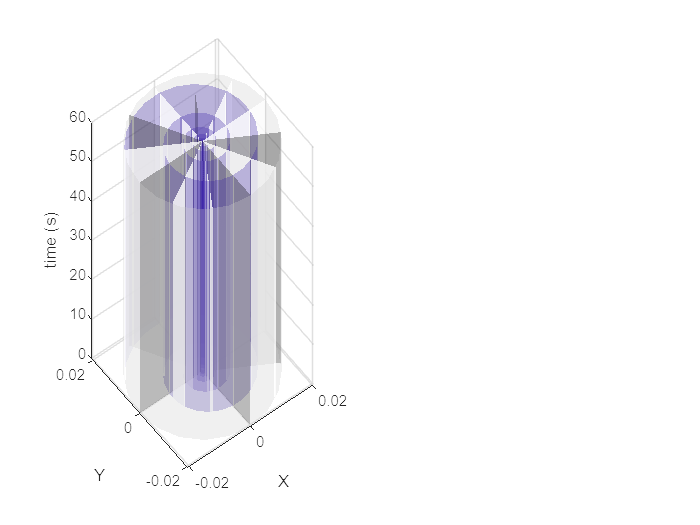

% drawing two graph
tiledlayout(1,2)
ax_3D = nexttile(1);

% drawing cyinders
[x y z_c] = cylinder(R);
ax_3D_cyl = surf(x, y, z_c*(H),'FaceColor',[.8 .8 .8],'EdgeAlpha',0, 'FaceAlpha',.3);
hold on;

% drawing spiral surf
P = 2; % parted

f_P = f_i*r.^(-32+note_i:1/P:N-2);
theta_P = pi/2 - 2*pi*log2(f_P/f_i);
A_P = 1./f_P;

[x y] = pol2cart(theta_P, A_P);
z_s = zeros(1, length(x));
ax_3D_spir = surf([x; x], [y; y], [z_s; z_s+H],'EdgeAlpha',0, 'FaceAlpha',.3);

% drawing white key
[xw yw] = pol2cart(wk, R);
[xb yb] = pol2cart(bk, R);

zero = zeros(1, length(xw));
x = reshape([zero; xw],1,[]);
y = reshape([zero; yw],1,[]);
z_w = zeros(1, length(xw)*2);
ax_3D_wk = surf([x; x], [y; y], [z_w;z_w+H],'FaceColor','w', 'FaceAlpha',.8, 'EdgeAlpha',0);

% drawing black key
zero = zeros(1, length(xb));
x = reshape([zero; xb],1,[]);
y = reshape([zero; yb],1,[]);
z_b = zeros(1, length(xb)*2);

ax_3D_bk = surf([x; x], [y; y], [z_b;z_b+H],'FaceColor','black', 'FaceAlpha',.3, 'EdgeAlpha',0);

xlabel('X')
ylabel('Y')
zlabel('time (s)')

max_note = length(theta)

max_note = 73

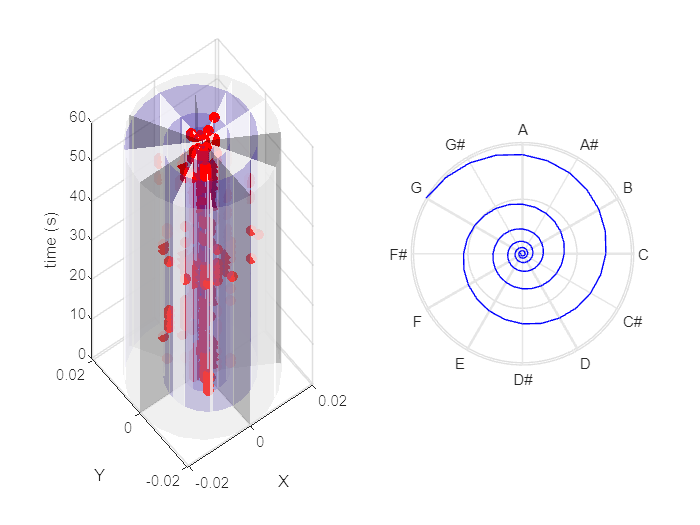


% Piano Note
for i=1:length(note_on)

    if isempty(note_off) && i~=length(note_on)
        note = [note_on(i,:).' ; note_on(i+1,:).'];
    elseif isempty(note_off)
        note = [note_on(i,:).' ; H];
    else
        note = [note_on(i,:).' ; note_off(i,3)]; % add end time ( ** modify - Working on it above )
    end

    n = note(1); v = note(2); st = note(3); et = note(4); 
    idx = n - note_i; % MIDI note number = Matlab index
    
    if (idx < max_note)
        [x y] = pol2cart(theta(idx), A(idx));
        plot3(x,y,st,'ro', 'MarkerFaceColor', 'r');
    end

    plot3([x x],[y y],[st et], 'r-', 'linewidth',3);
end    

% Second Gragh (2D Sheet)
ax_2D = nexttile(2);

for i=1:7 % white key
    polarplot([0 wk(i)],[0 R],'color',[.9 .9 .9],'linewidth',1.5)
    hold on
end

for i=1:5 % black key
    polarplot([0 bk(i)],[0 R],'color',[.9 .9 .9],'linewidth',0.1) % Color include alpha value
    hold on
end

polarplot(theta_P, A_P,'b-')
rlim([0 R])
set(gca,'thetaticklabel',{'C' 'B' 'A#' 'A' 'G#' 'G' 'F#' 'F' 'E' 'D#' 'D' 'C#' })
set(gca,'rticklabel',[])
hold on                                                

% Moving Z-plane
mesh_P = R/10;
[X,Y,Z] = meshgrid(-R-mesh_P:mesh_P:R+mesh_P,-R-mesh_P:mesh_P:R+mesh_P,0);

hold on
Spiral_plane = polarplot(0,0,'ro'); % change to function (to optimization)
Spiral_plane_line = polarplot([0,0],[0 0],'r-');

Z_plane = surf(ax_3D, X,Y,Z, 'FaceColor','c','FaceAlpha',.2, 'EdgeAlpha',0);
hold off

% Moving Spiral
h_P = 0.1;
s_P = 20 % time split

s_P = 20

note_list = []; % to Draw in-note
note_off_list = [];
i = 1;

on_note_num = size(note_on)

on_note_num =    793     3


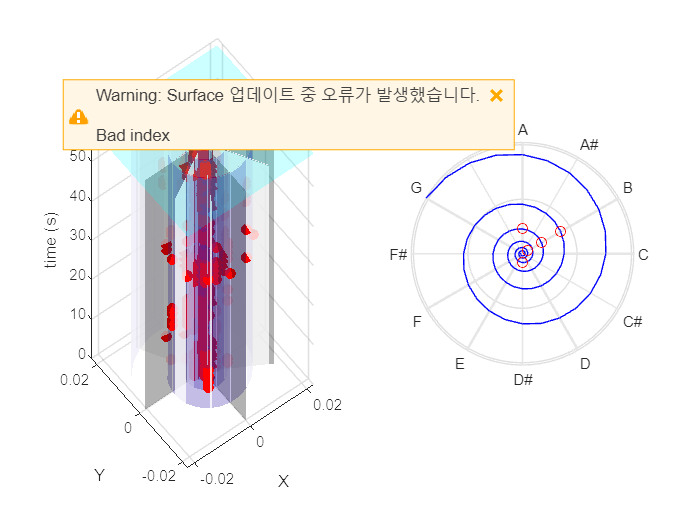

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 146

i = 147

i = 148

i = 149

i = 150

i = 151

i = 152

i = 153

i = 154

i = 155

i = 156

i = 157

i = 158

i = 159

i = 160

i = 161

i = 162

i = 163

i = 164

i = 165

i = 166

i = 167

i = 168

i = 169

i = 170

i = 171

i = 172

i = 173

i = 174

i = 175

i = 176

i = 177

i = 178

i = 179

i = 180

i = 181

i = 182

i = 183

i = 184

i = 185

i = 186

i = 187

i = 188

i = 189

i = 190

i = 191

i = 192

i = 193

i = 194

i = 195

i = 196

i = 197

i = 198

i = 199

i = 200

i = 201

i = 202

i = 203

i = 204

i = 205

i = 206

i = 207

i = 208

i = 209

i = 210

i = 211

i = 212

i = 213

i = 214

i = 215

i = 216

i = 217

i = 218

i = 219

i = 220

i = 221

i = 222

i = 223

i = 224

i = 225

i = 226

i = 227

i = 228

i = 229

i = 230

i = 231

i = 232

i = 233

i = 234

i = 235

i = 236

i = 237

i = 238

i = 239

i = 240

i = 241

i = 242

i = 243

i = 244

i = 245

i = 246

i = 247

i = 248

i = 249

i = 250

i = 251

i = 252

i = 253

i = 254

i = 255

i = 256

i = 257

i = 258

i = 259

i = 260

i = 261

i = 262

i = 263

i = 264

i = 265

i = 266

i = 267

i = 268

i = 269

i = 270

i = 271

i = 272

i = 273

i = 274

i = 275

i = 276

i = 277

i = 278

i = 279

i = 280

i = 281

i = 282

i = 283

i = 284

i = 285

i = 286

i = 287

i = 288

i = 289

i = 290

i = 291

i = 292

i = 293

i = 294

i = 295

i = 296

i = 297

i = 298

i = 299

i = 300

i = 301

i = 302

i = 303

i = 304

i = 305

i = 306

i = 307

i = 308

i = 309

i = 310

i = 311

i = 312

i = 313

i = 314

i = 315

i = 316

i = 317

i = 318

i = 319

i = 320

i = 321

i = 322

i = 323

i = 324

i = 325

i = 326

i = 327

i = 328

i = 329

i = 330

i = 331

i = 332

i = 333

i = 334

i = 335

i = 336

i = 337

i = 338

i = 339

i = 340

i = 341

i = 342

i = 343

i = 344

i = 345

i = 346

i = 347

i = 348

i = 349

i = 350

i = 351

i = 352

i = 353

i = 354

i = 355

i = 356

i = 357

i = 358

i = 359

i = 360

i = 361

i = 362

i = 363

i = 364

i = 365

i = 366

i = 367

i = 368

i = 369

i = 370

i = 371

i = 372

i = 373

i = 374

i = 375

i = 376

i = 377

i = 378

i = 379

i = 380

i = 381

i = 382

i = 383

i = 384

i = 385

i = 386

i = 387

i = 388

i = 389

i = 390

i = 391

i = 392

i = 393

i = 394

i = 395

i = 396

i = 397

i = 398

i = 399

i = 400

i = 401

i = 402

i = 403

i = 404

i = 405

i = 406

i = 407

i = 408

i = 409

i = 410

i = 411

i = 412

i = 413

i = 414

i = 415

i = 416

i = 417

i = 418

i = 419

i = 420

i = 421

i = 422

i = 423

i = 424

i = 425

i = 426

i = 427

i = 428

i = 429

i = 430

i = 431

i = 432

i = 433

i = 434

i = 435

i = 436

i = 437

i = 438

i = 439

i = 440

i = 441

i = 442

i = 443

i = 444

i = 445

i = 446

i = 447

i = 448

i = 449

i = 450

i = 451

i = 452

i = 453

i = 454

i = 455

i = 456

i = 457

i = 458

i = 459

i = 460

i = 461

i = 462

i = 463

i = 464

i = 465

i = 466

i = 467

i = 468

i = 469

i = 470

i = 471

i = 472

i = 473

i = 474

i = 475

i = 476

i = 477

i = 478

i = 479

i = 480

i = 481

i = 482

i = 483

i = 484

i = 485

i = 486

i = 487

i = 488

i = 489

i = 490

i = 491

i = 492

i = 493

i = 494

i = 495

i = 496

i = 497

i = 498

i = 499

i = 500

i = 501

i = 502

i = 503

i = 504

i = 505

i = 506

i = 507

i = 508

i = 509

i = 510

i = 511

i = 512

i = 513

i = 514

i = 515

i = 516

i = 517

i = 518

i = 519

i = 520

i = 521

i = 522

i = 523

i = 524

i = 525

i = 526

i = 527

i = 528

i = 529

i = 530

i = 531

i = 532

i = 533

i = 534

i = 535

i = 536

i = 537

i = 538

i = 539

i = 540

i = 541

i = 542

i = 543

i = 544

i = 545

i = 546

i = 547

i = 548

i = 549

i = 550

i = 551

i = 552

i = 553

i = 554

i = 555

i = 556

i = 557

i = 558

i = 559

i = 560

i = 561

i = 562

i = 563

i = 564

i = 565

i = 566

i = 567

i = 568

i = 569

i = 570

i = 571

i = 572

i = 573

i = 574

i = 575

i = 576

i = 577

i = 578

i = 579

i = 580

i = 581

i = 582

i = 583

i = 584

i = 585

i = 586

i = 587

i = 588

i = 589

i = 590

i = 591

i = 592

i = 593

i = 594

i = 595

i = 596

i = 597

i = 598

i = 599

i = 600

i = 601

i = 602

i = 603

i = 604

i = 605

i = 606

i = 607

i = 608

i = 609

i = 610

i = 611

i = 612

i = 613

i = 614

i = 615

i = 616

i = 617

i = 618

i = 619

i = 620

i = 621

i = 622

i = 623

i = 624

i = 625

i = 626

i = 627

i = 628

i = 629

i = 630

i = 631

i = 632

i = 633

i = 634

i = 635

i = 636

i = 637

i = 638

i = 639

i = 640

i = 641

i = 642

i = 643

i = 644

i = 645

i = 646

i = 647

i = 648

i = 649

i = 650

i = 651

i = 652

i = 653

i = 654

i = 655

i = 656

i = 657

i = 658

i = 659

i = 660

i = 661

i = 662

i = 663

i = 664

i = 665

i = 666

i = 667

i = 668

i = 669

i = 670

i = 671

i = 672

i = 673

i = 674

i = 675

i = 676

i = 677

i = 678

i = 679

i = 680

i = 681

i = 682

i = 683

i = 684

i = 685

i = 686

i = 687

i = 688

i = 689

i = 690

i = 691

i = 692

i = 693

i = 694

i = 695

i = 696

i = 697

i = 698

i = 699

i = 700

i = 701

i = 702

i = 703

i = 704

i = 705

i = 706

i = 707

i = 708

i = 709

i = 710

i = 711

i = 712

i = 713

i = 714

i = 715

i = 716

i = 717

i = 718

i = 719

i = 720

i = 721

i = 722

i = 723

i = 724

i = 725

i = 726

i = 727

i = 728

i = 729

i = 730

i = 731

i = 732

i = 733

i = 734

i = 735

i = 736

i = 737

i = 738

i = 739

i = 740

i = 741

i = 742

i = 743

i = 744

i = 745

i = 746

i = 747

i = 748

i = 749

i = 750

i = 751

i = 752

i = 753

i = 754

i = 755

i = 756

i = 757

i = 758

i = 759

i = 760

i = 761

i = 762

i = 763

i = 764

i = 765

i = 766

i = 767

i = 768

i = 769

i = 770

i = 771

i = 772

i = 773

i = 774

i = 775

i = 776

i = 777

i = 778

i = 779

i = 780

i = 781

i = 782

i = 783

i = 784

i = 785

i = 786

i = 787

i = 788

i = 789

i = 790

i = 791

i = 792

i = 793

i = 794

% Initialization of VideoWriter object
videoFileName = 'output_video.avi'; % Specify the name of the output video file
videoWriter = VideoWriter(videoFileName); % Create the VideoWriter object
videoWriter.FrameRate = 15; % Set the frame rate (optional)
obj.Quality = 100;
open(videoWriter); % Open the file for writing

for h = 0:1/s_P:H % have to change h_p to H
    ax_3D_spir.ZData = [z_s; z_s+h];
    ax_3D_bk.ZData = [z_b; z_b+h];
    ax_3D_wk.ZData = [z_w; z_w+h];
    ax_3D_cyl.ZData = [z_c; z_c+h];

    % Z_Plane
    Z_plane.ZData = zeros(size(X))+h;

    % Find Note
    % need to modify / add final off condition ? 
    if i <= on_note_num(1)
        while (i<= on_note_num(1) && note_on(i,3)<=h)
            "<h";
            note_list = [note_list; note_on(i,:)];
            note_off_list = [note_off_list; note_off(i,:)];
            if i <= on_note_num(1)
                % pring progress
                i = i+1
            end
        end
    
        note_size = size(note_off_list);
    
        % Delete Note
        j = 1;
        while j <= note_size(1)
            if note_off_list(j,3)<=h
                ">h";
                note_list(j,:) = [];
                note_off_list(j,:) = [];
    
                j = j-1; note_size(1) = note_size(1)-1; % size update
            end
            j = j+1;
        end
    
        %{
        % -- note_off is empty
        if isempty(note_off) && i~=length(note_on)
            note = [note_on(i,:).' ; note_on(i+1,:).'];
        elseif isempty(note_off)
            note = [note_on(i,:).' ; H];
        
        % -- note_off is not empty 
        else
            note = [note_on(i,:).' ; note_off(i,3)]; % add end time ( ** modify - Working on it above )
        end
        %}
    
        %n = note(note_list); % v = note(2); st = note(3); et = note(4); 
        %n
        "draw";
        if isempty(note_list)
            Spiral_plane.XData = [];
            Spiral_plane.YData = [];
        
            Spiral_plane_line.XData = [];
            Spiral_plane_line.YData = [];
            
        else
            idx = note_list(:,1) - note_i; % MIDI note number = Matlab index

            A_s = A([idx]);
            theta_s = theta([idx]);
    
            Spiral_plane.XData = theta_s;
            Spiral_plane.YData = A_s;
        
            %Spiral_plane_line.XData = [0 theta_s];
            %Spiral_plane_line.YData = [0 A_s];
        end
    
        drawnow

        % Capture the current figure as a frame
    frame = getframe(gcf);
    writeVideo(videoWriter, frame); % Write the frame to the video

    end

    % Capture the current figure as a frame
    frame = getframe(gcf);
    writeVideo(videoWriter, frame); % Write the frame to the video

    drawnow
end

% Close the VideoWriter object
close(videoWriter);

% Close the VideoWriter object
close(videoWriter);

## Synthesize MIDI Messages

This example plays parsed MIDI messages using a simple monophonic synthesizer. To see a demonstration of this synthesizer, see [Design and Play a MIDI Synthesizer](docid:audio_ug#mw_9cb34f1f-767f-42a8-b6c7-c33d9546923a). 

% Initialize System objects for playing MIDI messages
%osc = audioOscillator('square', 'Amplitude', 0,'DutyCycle',0.75);
%deviceWriter = audioDeviceWriter;

% - - Play Audio
%simplesynth(msgArray,osc,deviceWriter);

You can also send parsed MIDI messages to a MIDI device using [`midisend`](docid:audio_ref#mw_ee7bc3c1-86e5-4047-92ee-d8c60dfac44d). For more information about interacting with MIDI devices using MATLAB, see [MIDI Device Interface](docid:audio_ug#mw_66a38da2-303f-4ffe-9948-e67eb0d3fdd6).

## Helper Functions

### Read Delta-Times

function [valueOut,byteLength] = findVariableLength(lengthIndex,readOut)

byteStream = zeros(4,1);

for i = 1:4
    valCheck = readOut(lengthIndex+i);
    byteStream(i) = bitand(valCheck,127);   % Mask MSB for value
    if ~bitand(valCheck,uint32(128))        % If MSB is 0, no need to append further
        break
    end
end

valueOut = polyval(byteStream(1:i),128);    % Base is 128 because 7 bits are used for value
byteLength = i;

end

### Interpret MIDI Messages

function [statusOut,lenOut,message] = interpretMessage(statusIn,eventIn,readOut)

% Check if running status
introValue = readOut(eventIn+1);
if isStatusByte(introValue)
    statusOut = introValue;         % New status
    running = false;
else
    statusOut = statusIn;           % Running status—Keep old status
    running = true;
end

switch statusOut
    case 255     % Meta-event (FF)—IGNORE
        [eventLength, lengthLen] = findVariableLength(eventIn+2, ...
            readOut);   % Meta-events have an extra byte for type of meta-event
        lenOut = 2+lengthLen+eventLength;
        message = -1;
    case 240     % Sysex message (F0)—IGNORE
        [eventLength, lengthLen] = findVariableLength(eventIn+1, ...
            readOut);
        lenOut = 1+lengthLen+eventLength;
        message = -1;
        
    case 247     % Sysex message (F7)—IGNORE
        [eventLength, lengthLen] = findVariableLength(eventIn+1, ...
            readOut);
        lenOut = 1+lengthLen+eventLength;
        message = -1;
    otherwise    % MIDI message—READ
        eventLength = msgnbytes(statusOut);
        if running  
            % Running msgs don't retransmit status—Drop a bit
            lenOut = eventLength-1;
            message = uint8([statusOut;readOut(eventIn+(1:lenOut))]);
            
        else
            lenOut = eventLength;
            message = uint8(readOut(eventIn+(1:lenOut)));
        end
end

end

% ----

function n = msgnbytes(statusByte)

if statusByte <= 191        % hex2dec('BF')
    n = 3;
elseif statusByte <= 223    % hex2dec('DF')
    n = 2;
elseif statusByte <= 239    % hex2dec('EF')
    n = 3;
elseif statusByte == 240    % hex2dec('F0')
    n = 1;
elseif statusByte == 241    % hex2dec('F1')
    n = 2;
elseif statusByte == 242    % hex2dec('F2')
    n = 3;
elseif statusByte <= 243    % hex2dec('F3')
    n = 2;
else
    n = 1;
end

end

% ----

function yes = isStatusByte(b)
yes = b > 127;
end

### Create MIDI Messages

function [tsOut,msgOut] = createMessage(messageIn,tsIn,deltaTimeIn,ticksPerQNoteIn,bpmIn)

if messageIn < 0     % Ignore Sysex message/meta-event data
    tsOut = tsIn;
    msgOut = midimsg(0);
    return
end

% Create RawBytes field
messageLength = length(messageIn);
zeroAppend = zeros(8-messageLength,1);
bytesIn = transpose([messageIn;zeroAppend]);

% deltaTimeIn and ticksPerQNoteIn are both uints
% Recast both values as doubles
d = double(deltaTimeIn);
t = double(ticksPerQNoteIn);

% Create Timestamp field and tsOut
msPerQNote = 6e7/bpmIn;
timeAdd = d*(msPerQNote/t)/1e6;
tsOut = tsIn+timeAdd;

% Create midimsg object
midiStruct = struct('RawBytes',bytesIn,'Timestamp',tsOut);
msgOut = midimsg.fromStruct(midiStruct);

end

## Play MIDI Messages Using a Synthesizer

function simplesynth(msgArray,osc,deviceWriter)

i = 1;
tic
endTime = msgArray(length(msgArray)).Timestamp;

while toc < endTime
    if toc >= msgArray(i).Timestamp     % At new note, update deviceWriter
        msg = msgArray(i);      
        i = i+1;
        if isNoteOn(msg)
            osc.Frequency = note2freq(msg.Note);
            osc.Amplitude = msg.Velocity/127;
        elseif isNoteOff(msg)
            if msg.Note == msg.Note
                osc.Amplitude = 0;
            end
        end
    end
    deviceWriter(osc());    % Keep calling deviceWriter as it is updated
end

end

% ----

function yes = isNoteOn(msg)
yes = strcmp(msg.Type,'NoteOn') ...
    && msg.Velocity > 0;
end

% ----

function yes = isNoteOff(msg)
yes = strcmp(msg.Type,'NoteOff') ...
    || (strcmp(msg.Type,'NoteOn') && msg.Velocity == 0);
end

% ----

function freq = note2freq(note)
freqA = 440;
noteA = 69;
freq = freqA * 2.^((note-noteA)/12);
end

*Copyright 2018 The MathWorks, Inc.*